# (Unconstrained) 2D tests of HMIP

# Hopfield iterations:11


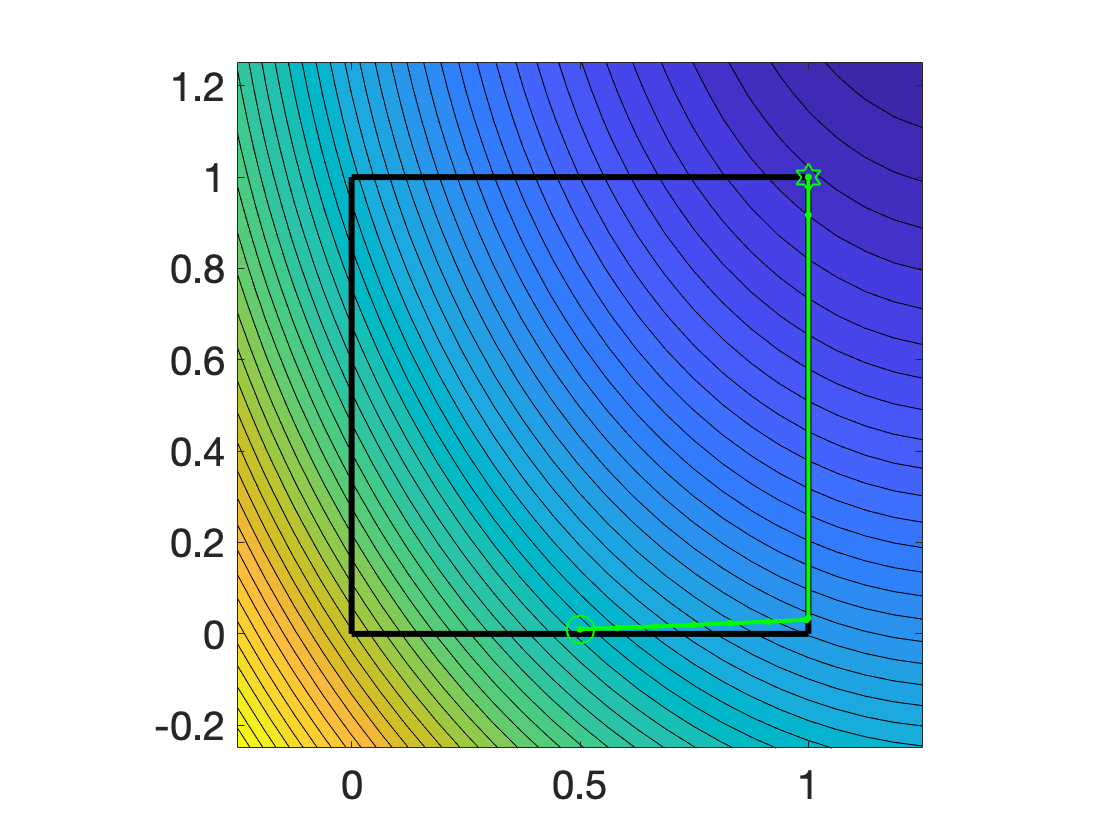

ans =   VisualizeHMIP with properties:

    count_figure: 2


Q=[2,0;0,1];
q=[-2.7;-1.8];
objective=@(x) 0.5*x'*Q*x+q'*x;
gradient=@(x) Q*x+q;
lb=0;
ub=1;
problem=problemHMIP('objective',objective,'gradient',gradient,'size',2,'binary_index',[1;0],'lb',lb,'ub',ub);
options=OptionsHMIP('num_iterations_max',300,'keep_hopfield_trajectory',1,'activation_type','pwl','direction_method','binary');
solver=solverHMIP('problem',problem,'options',options);
[x_h,x]=solver.main_hopfield;
solver.visualize.phase_portrait_2D(x,Q,q,lb,ub)

# Hopfield iterations:908


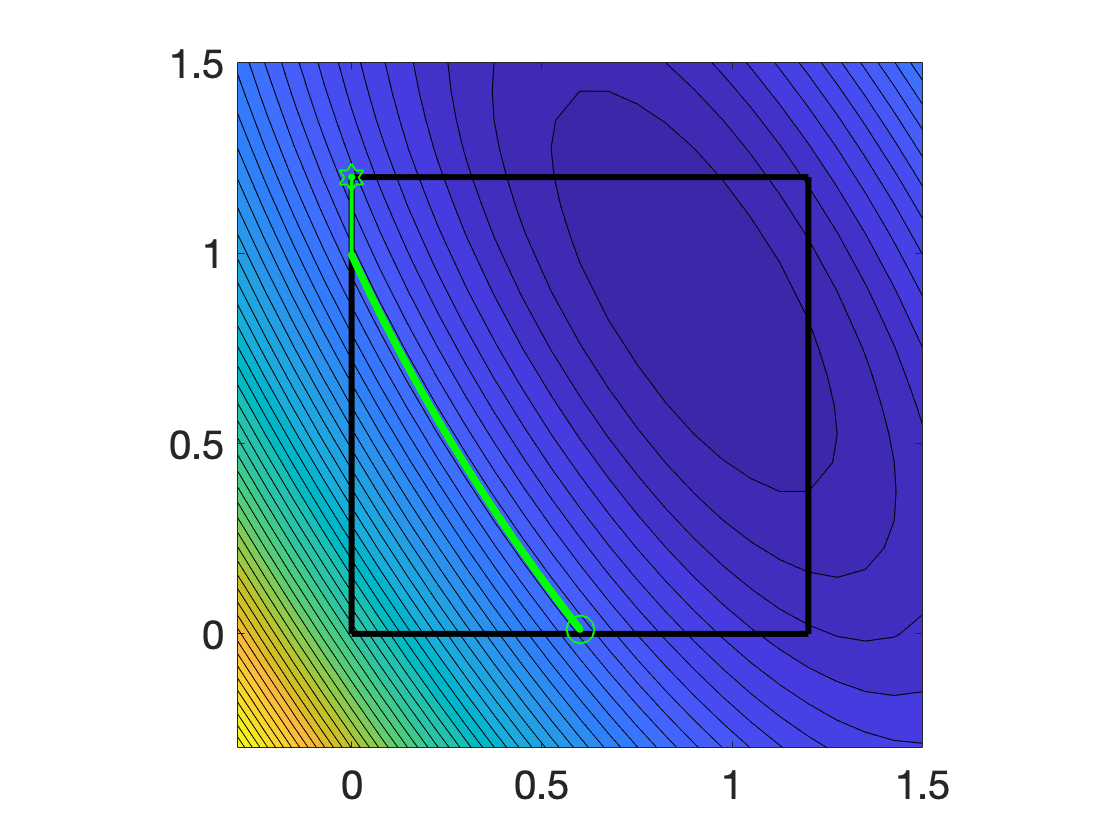

ans =   VisualizeHMIP with properties:

    count_figure: 2


Q=[2,1;1,1];
q=[-2.7;-1.8];
objective=@(x) 0.5*x'*Q*x+q'*x;
gradient=@(x) Q*x+q;
ub=1.2;
lb=0;
problem=problemHMIP('objective',objective,'gradient',gradient,'size',2,'binary_index',[1;0],'lb',lb,'ub',ub);
options=OptionsHMIP('num_iterations_max',3000,'keep_hopfield_trajectory',1,'activation_type','pwl','direction_method','binary');
solver=solverHMIP('problem',problem,'options',options);
[x_h,x]=solver.main_hopfield;
solver.visualize.phase_portrait_2D(x,Q,q,lb,ub)

# Hopfield iterations:34


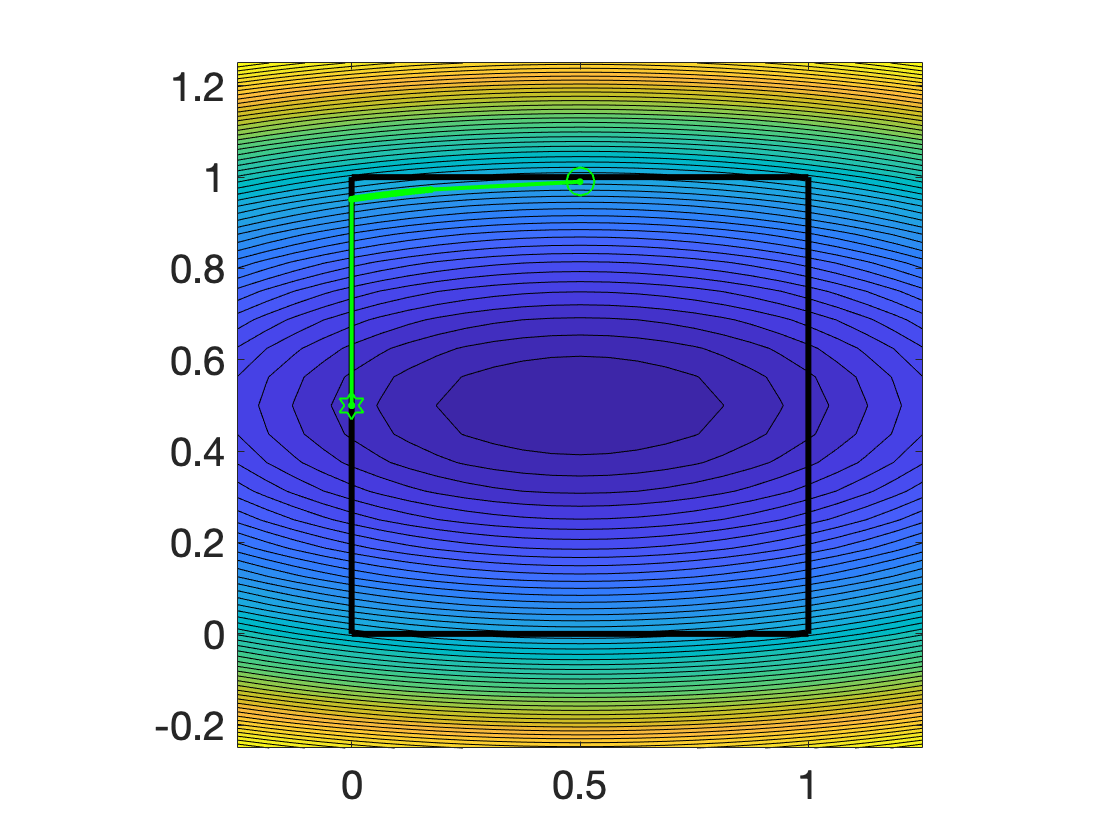

ans =   VisualizeHMIP with properties:

    count_figure: 2


Q=[2,0;0,16];
q=[-1;-8];
objective=@(x) 0.5*x'*Q*x+q'*x;
gradient=@(x) Q*x+q;
lb=0;
ub=1;
problem=problemHMIP('objective',objective,'gradient',gradient,'size',2,'binary_index',[1;0],'lb',lb,'ub',ub);
options=OptionsHMIP('num_iterations_max',100,'keep_hopfield_trajectory',1,'activation_type','pwl','direction_method','binary');
solver=solverHMIP('problem',problem,'options',options);
[x_h,x]=solver.main_hopfield;
solver.visualize.phase_portrait_2D(x,Q,q,lb,ub)

# Hopfield iterations:10000


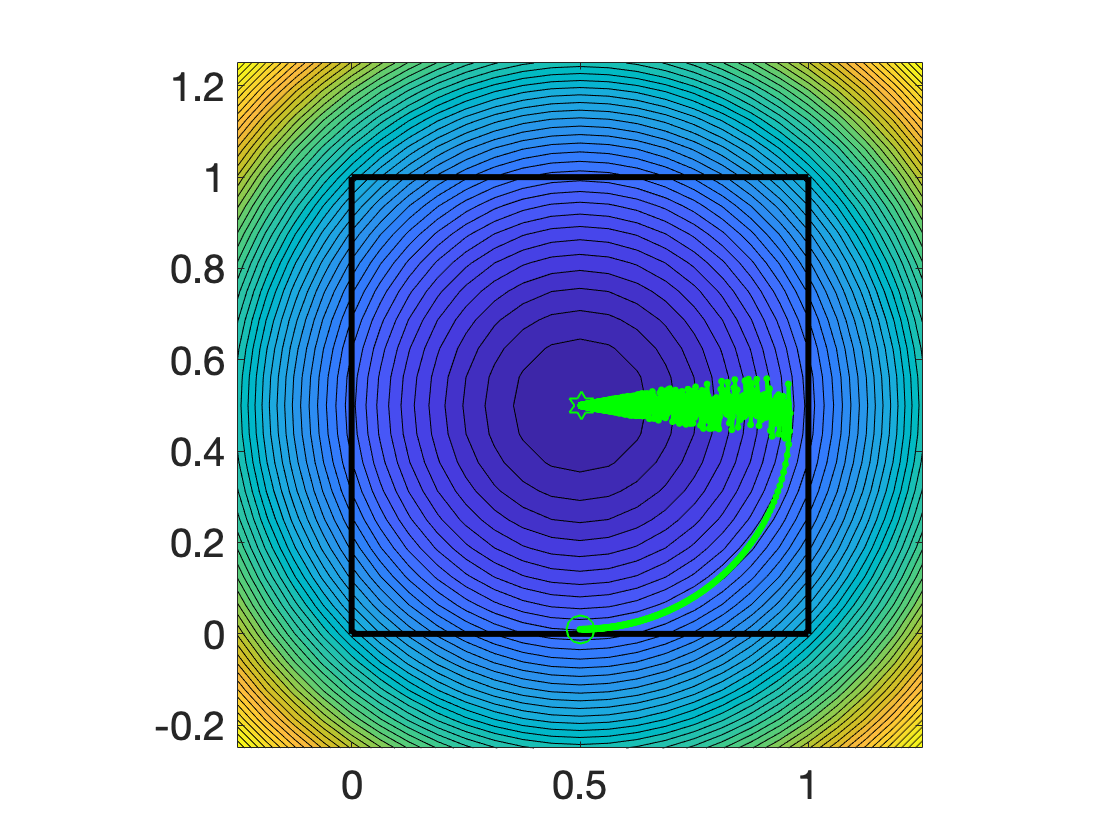

ans =   VisualizeHMIP with properties:

    count_figure: 2


Q=[2 0;0 2];
q=[-1;-1];
objective=@(x) 0.5*x'*Q*x+q'*x;
gradient=@(x) Q*x+q;
lb=0;
ub=1;
problem=problemHMIP('objective',objective,'gradient',gradient,'size',2,'binary_index',[1;0],'lb',lb,'ub',ub);
options=OptionsHMIP('num_iterations_max',10000,'keep_hopfield_trajectory',1,'activation_type','pwl','direction_method','binary','beta',[10;1]);
solver=solverHMIP('problem',problem,'options',options);
[x_h,x]=solver.main_hopfield;
solver.visualize.phase_portrait_2D(x,Q,q,lb,ub)

# Hopfield iterations:10000


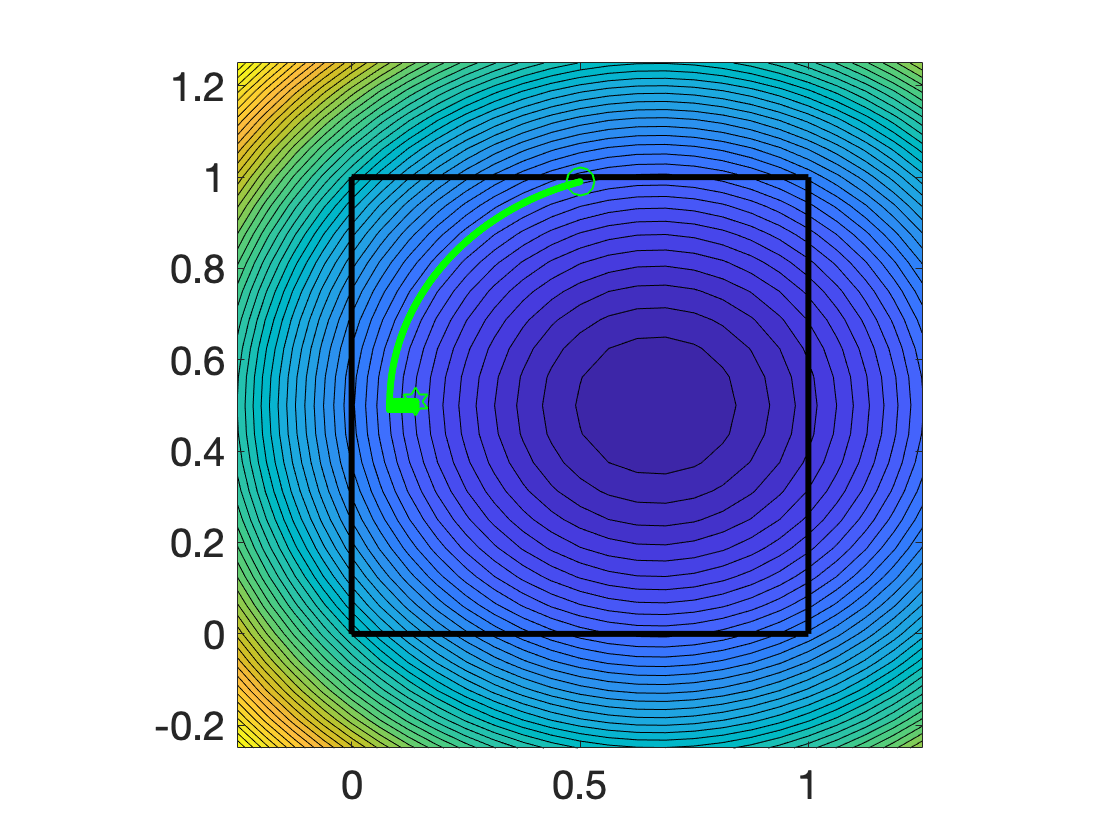

ans =   VisualizeHMIP with properties:

    count_figure: 2


Q=[1.5 0;0 2];
q=[-1;-1];
objective=@(x) 0.5*x'*Q*x+q'*x;
gradient=@(x) Q*x+q;
lb=0;
ub=1;
problem=problemHMIP('objective',objective,'gradient',gradient,'size',2,'binary_index',[1;0]);
options=OptionsHMIP('num_iterations_max',10000,'keep_hopfield_trajectory',1,'activation_type','pwl','direction_method','binary','beta',[1;1]);
solver=solverHMIP('problem',problem,'options',options);
[x_h,x]=solver.main_hopfield;
solver.visualize.phase_portrait_2D(x,Q,q,lb,ub)